**Session 01**

Run GLM for NeuralCoding01 
V1 # of Voxel: 1428 
Eccen mask: 805 / 1428 selected 
Rsqur mask: 764 / 805 selected 
ConstrumtSinai:  000%  |                                          | 0/1it [00:00:00<Inf:NaN:NaN, Inf s/it]
Elapsed time is 3.206692 seconds.



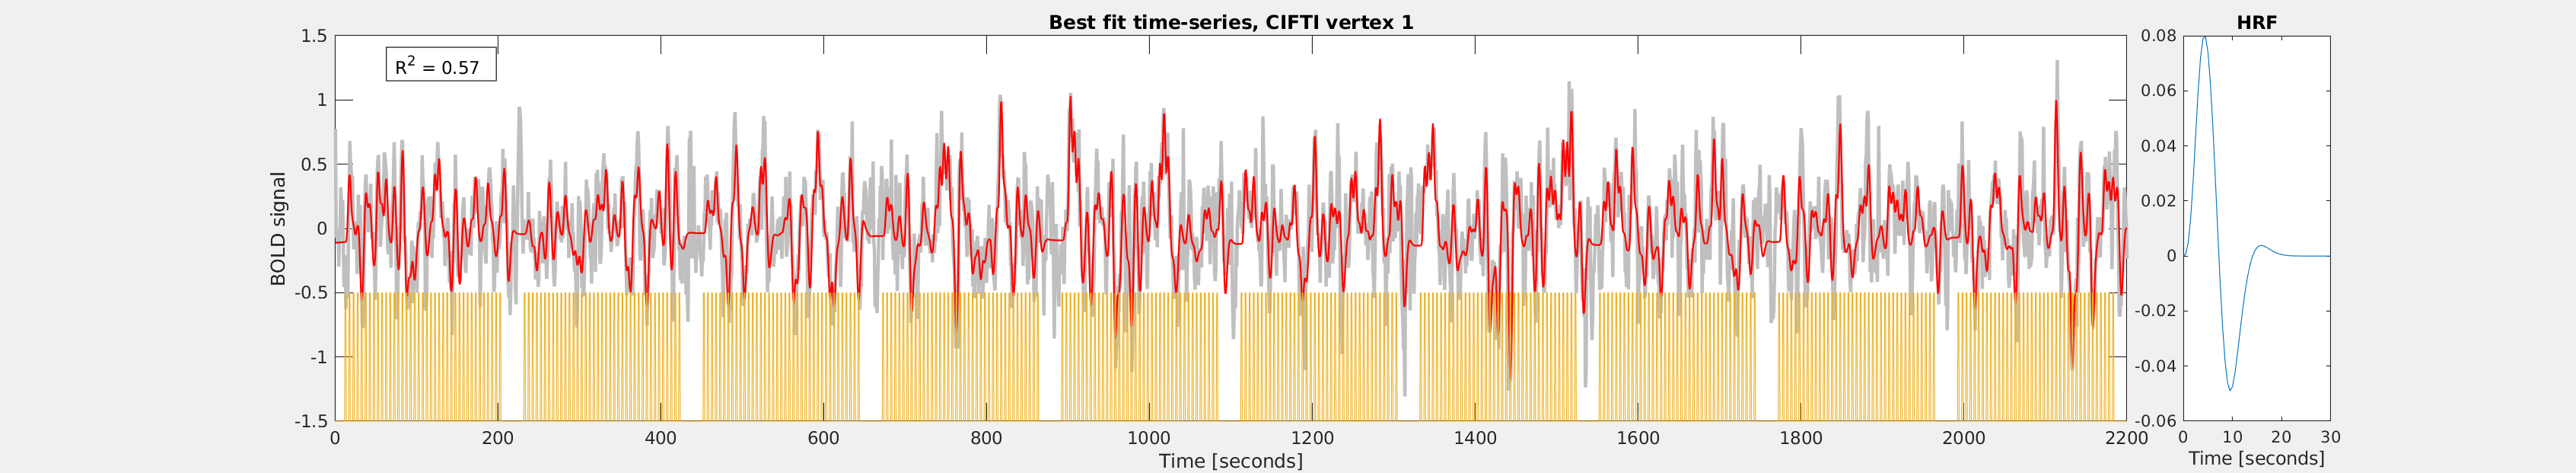

V2 # of Voxel: 1115 
Eccen mask: 675 / 1115 selected 
Rsqur mask: 611 / 675 selected 
ConstrumtSinai:  000%  |                                          | 0/1it [00:00:00<Inf:NaN:NaN, Inf s/it]
Elapsed time is 3.431936 seconds.



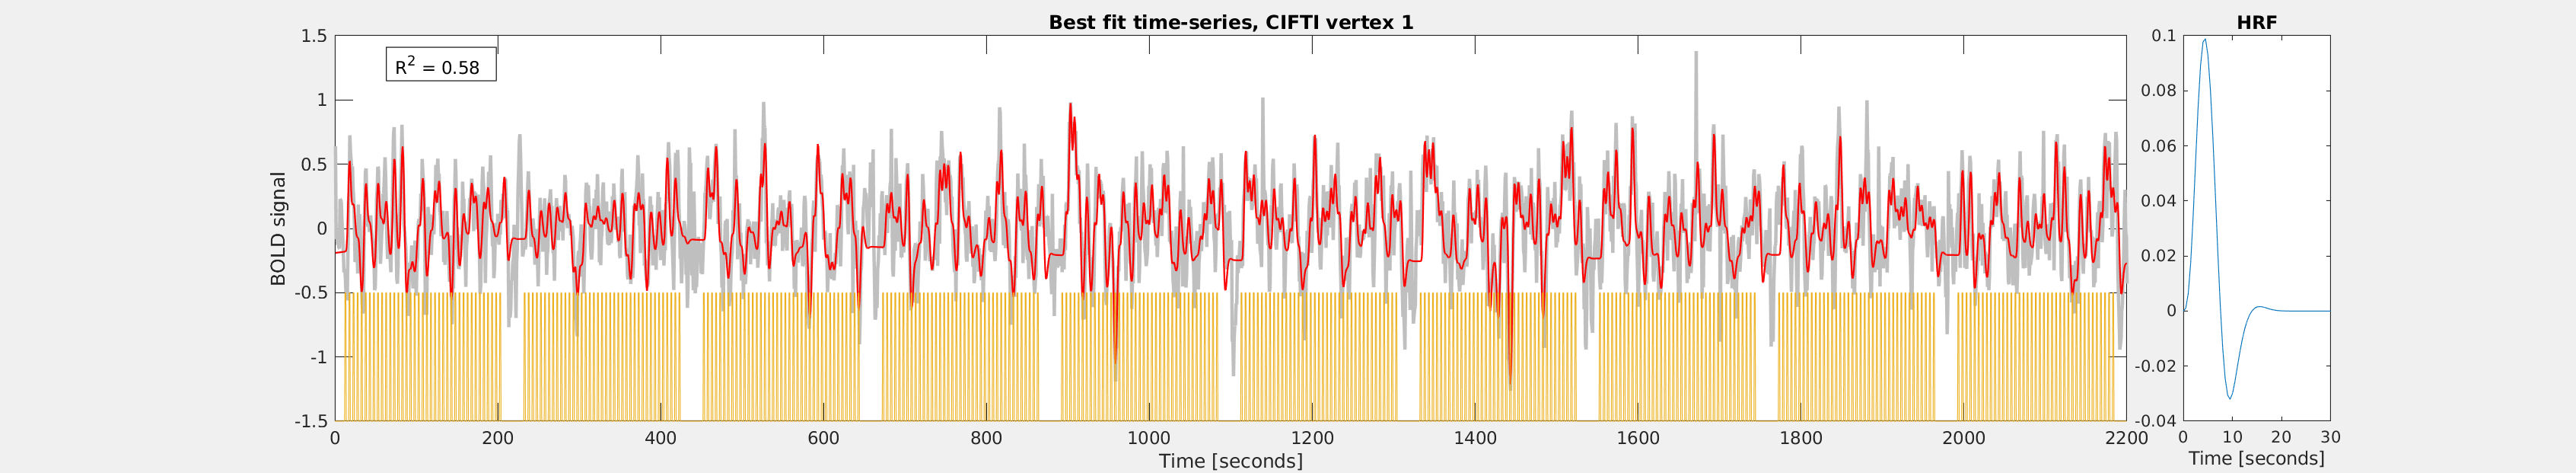

V3 # of Voxel: 976 
Eccen mask: 674 / 976 selected 
Rsqur mask: 642 / 674 selected 
ConstrumtSinai:  000%  |                                          | 0/1it [00:00:00<Inf:NaN:NaN, Inf s/it]
Elapsed time is 3.374812 seconds.



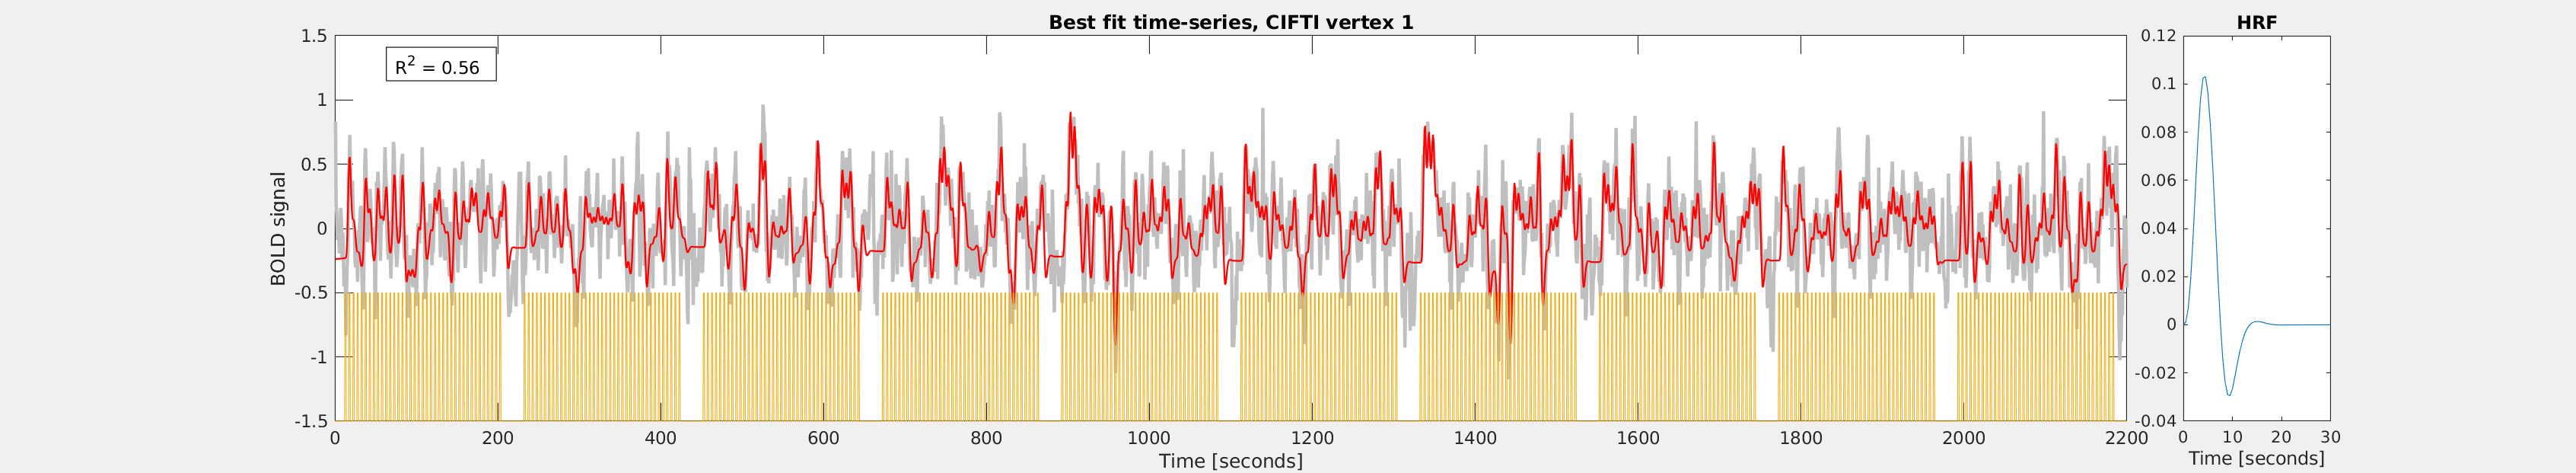

% Run fit for S1
fit_session(1)

**Session 02**

Run GLM for NeuralCoding02 
V1 # of Voxel: 1428 
Eccen mask: 805 / 1428 selected 
Rsqur mask: 764 / 805 selected 
ConstrmtSinai:  000%  |                                          | 0/1it [00:00:00<Inf:NaN:NaN, Inf s/it]
Elapsed time is 2.411697 seconds.



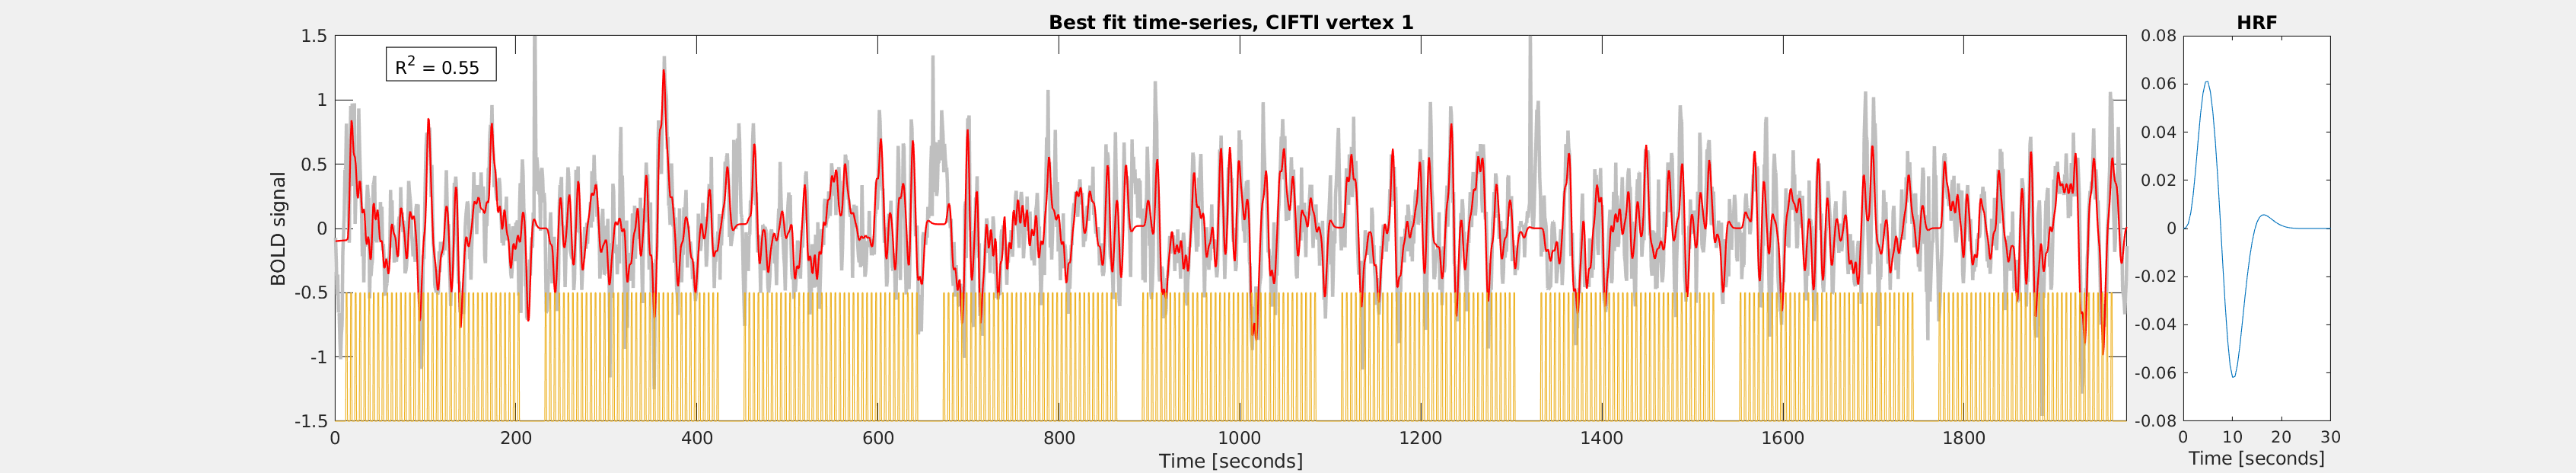

V2 # of Voxel: 1115 
Eccen mask: 675 / 1115 selected 
Rsqur mask: 611 / 675 selected 
ConstrmtSinai:  000%  |                                          | 0/1it [00:00:00<Inf:NaN:NaN, Inf s/it]
Elapsed time is 3.410369 seconds.



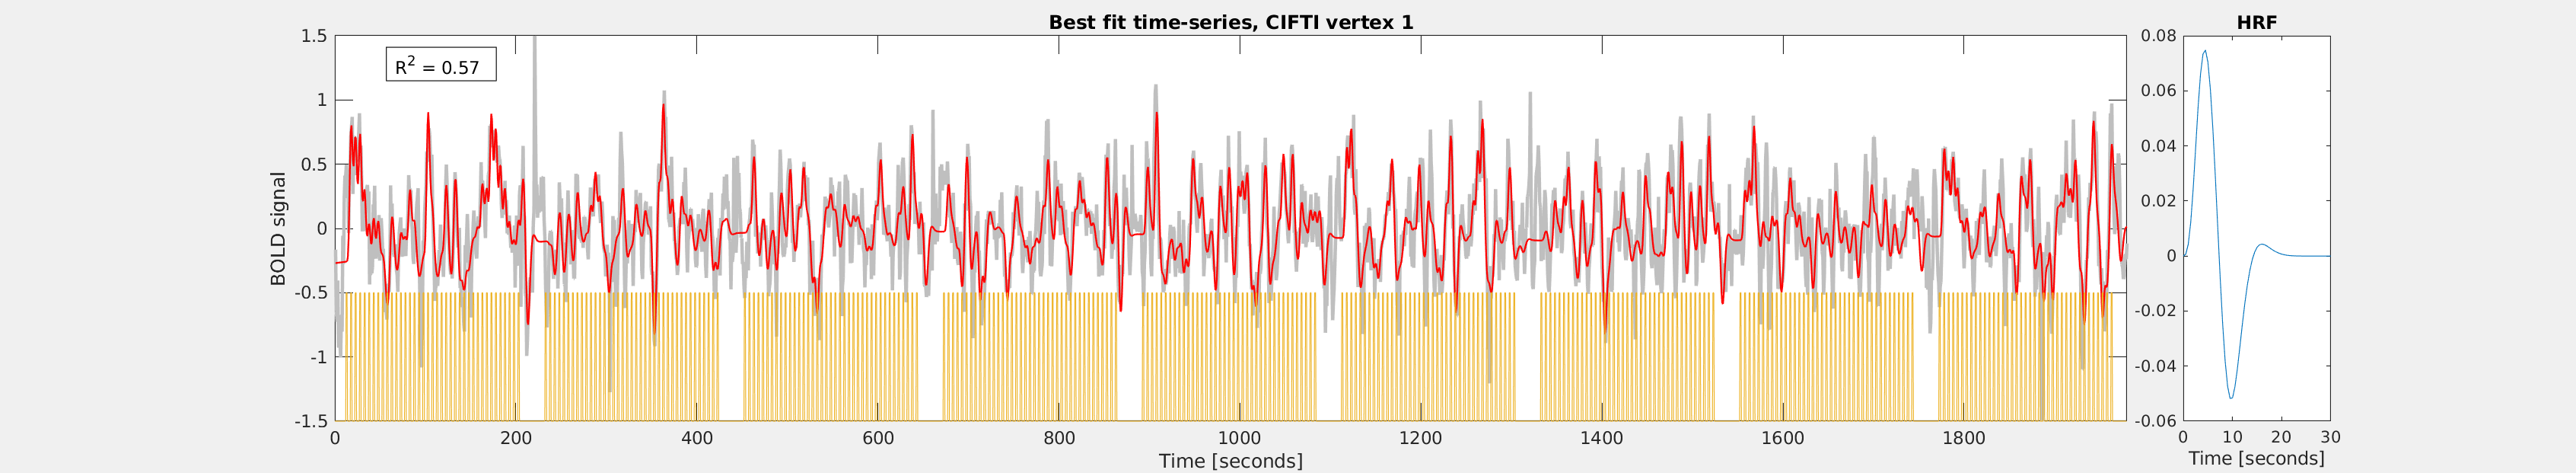

V3 # of Voxel: 976 
Eccen mask: 674 / 976 selected 
Rsqur mask: 642 / 674 selected 
ConstrmtSinai:  000%  |                                          | 0/1it [00:00:00<Inf:NaN:NaN, Inf s/it]
Elapsed time is 2.773492 seconds.



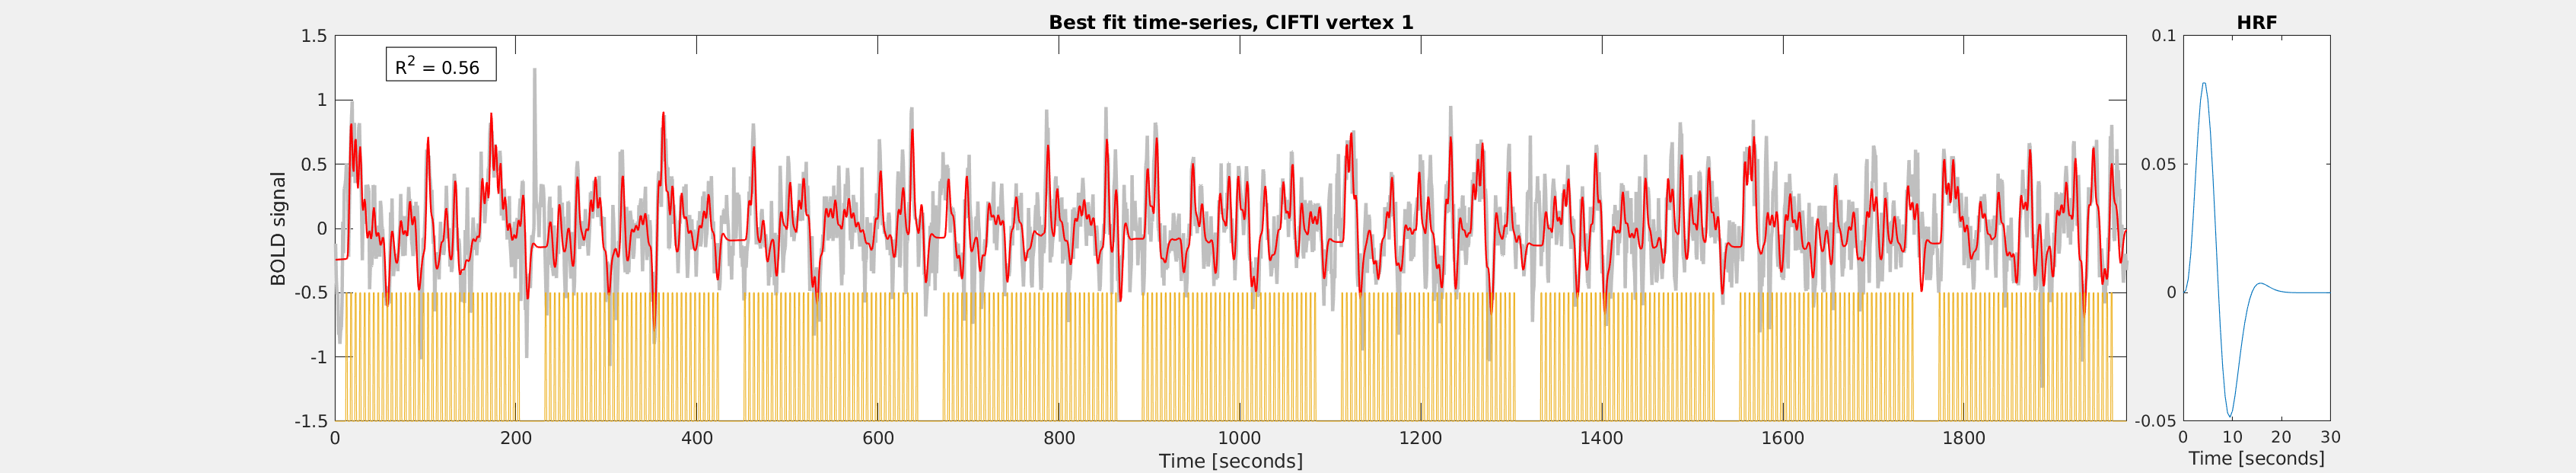

% Run fit for S1
fit_session(2)

**Session 03**

Run GLM for NeuralCoding03 
V1 # of Voxel: 1428 
Eccen mask: 805 / 1428 selected 
Rsqur mask: 764 / 805 selected 
ConstrumtSinai:  000%  |                                          | 0/1it [00:00:00<Inf:NaN:NaN, Inf s/it]
Elapsed time is 3.951602 seconds.



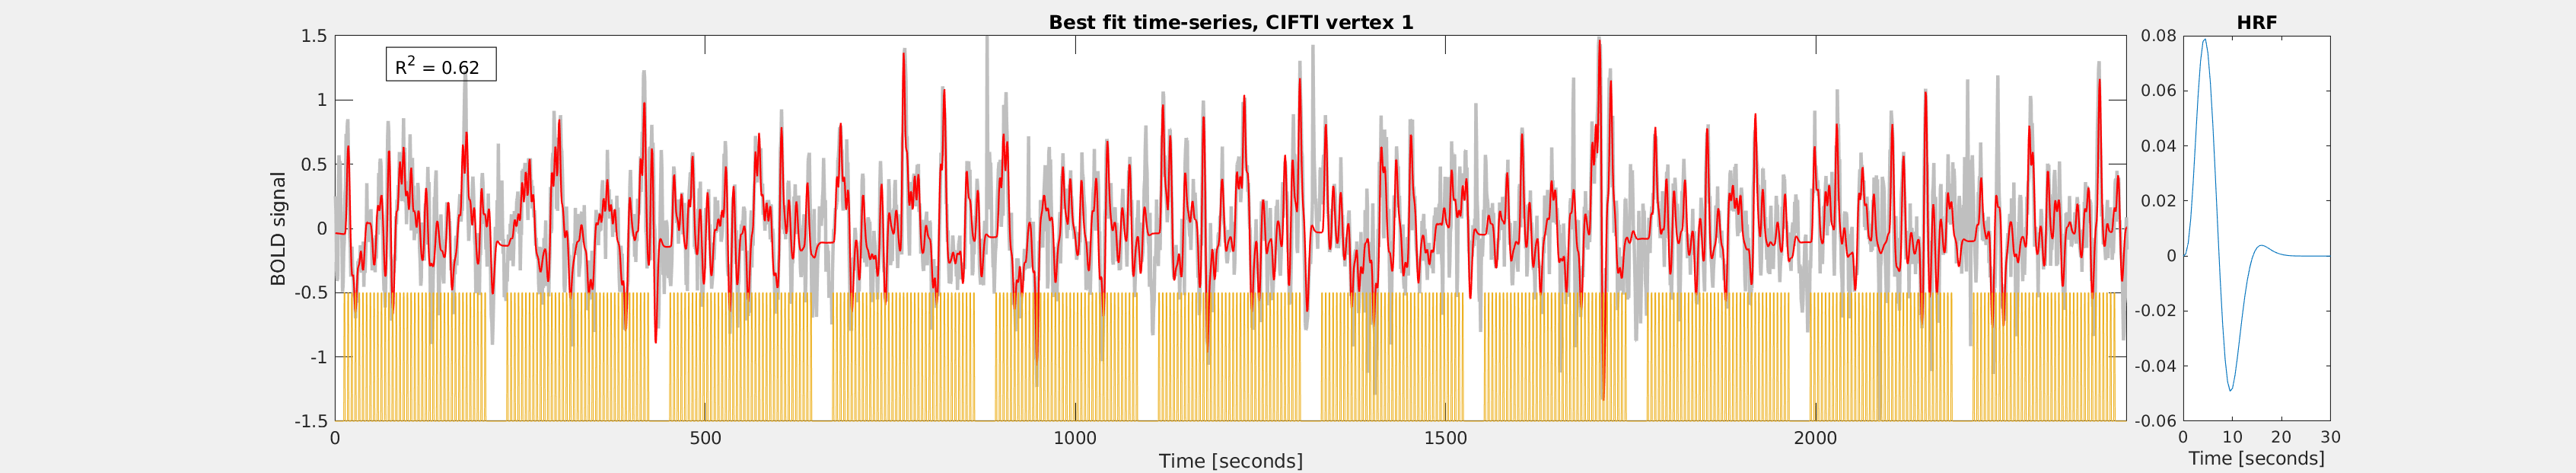

V2 # of Voxel: 1115 
Eccen mask: 675 / 1115 selected 
Rsqur mask: 611 / 675 selected 
ConstrumtSinai:  000%  |                                          | 0/1it [00:00:00<Inf:NaN:NaN, Inf s/it]
Elapsed time is 4.287448 seconds.



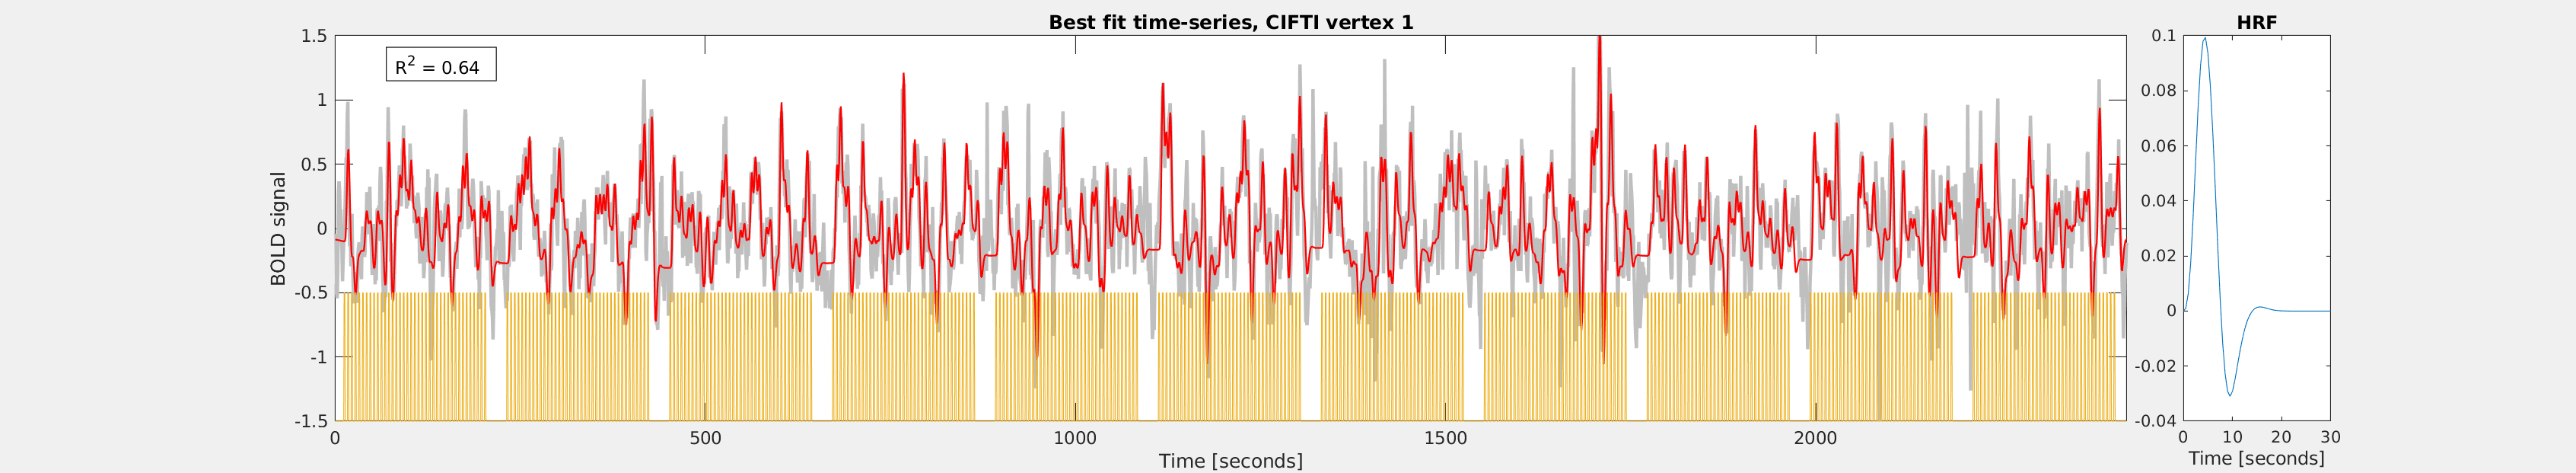

V3 # of Voxel: 976 
Eccen mask: 674 / 976 selected 
Rsqur mask: 642 / 674 selected 
ConstrumtSinai:  000%  |                                          | 0/1it [00:00:00<Inf:NaN:NaN, Inf s/it]
Elapsed time is 4.523298 seconds.



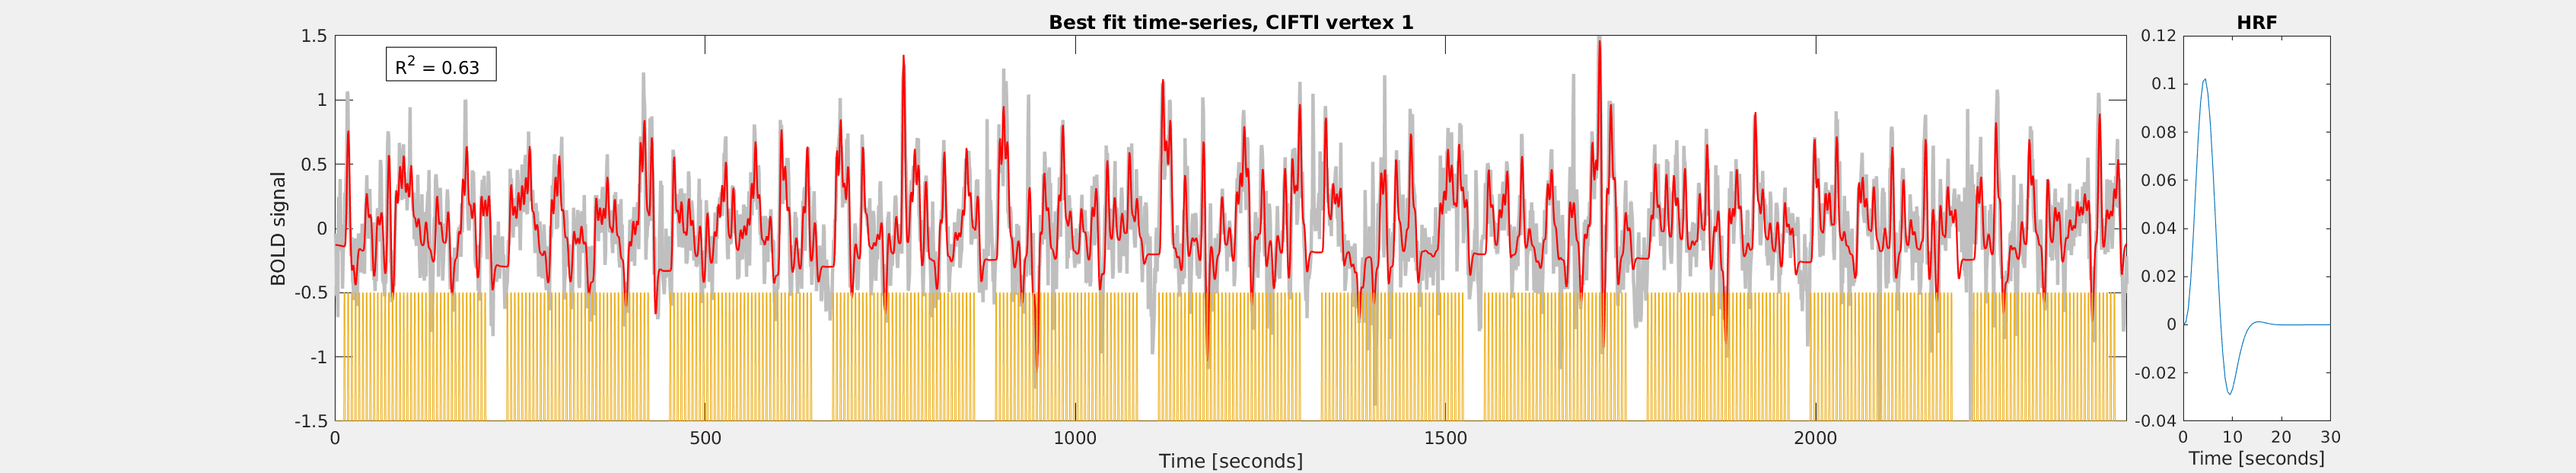

% Run fit for S1
fit_session(3)

Function that fit the median voxel values in V1 - V3

function fit_session(ses_idx)
sub_name = 'HERO_LZ';
acq_base = 'NeuralCoding%02d';

nRuns = [10, 9, 11];
acq_idx = {1:nRuns(1), 1:nRuns(2), 0:(nRuns(3) - 1)};
base_idx = [0, 10, 19];
icafix = false;

acq_type = sprintf(acq_base, ses_idx);
fprintf('Run GLM for %s \n', acq_type);

% load data defined by ROI
% run v1 through v3
for area = 1 : 3
    data = load_session(sub_name, acq_type, acq_idx{ses_idx}, icafix);
    roi_mask = define_roi(sub_name, 'areaIndex', area);
    
    data = data(roi_mask, :);
    medianTS = median(data, 1);
    
    % Run GLM model fit
    results = glm_fit(medianTS, [], base_idx, false);
    stim = sum(results.stim, 1);
    
     % Show the results figures
    figFields = fieldnames(results.figures);
    if ~isempty(figFields)
        for ii = 1:length(figFields)
            figHandle = struct2handle(results.figures.(figFields{ii}).hgS_070000,0,'convert');
            set(figHandle,'visible','on')                        
        end
                
        subplot(1, 10, 1:9);
        hold on;
        plot(results.stimTime, stim - 1.5);
        xlim([0, nRuns(ses_idx) * 220.0]);
        ylim([-1.5, 1.5]);        
    end
end
end